clc; clear all; close all;
rng(0);

## Import data from file [generated from the Import tool]

trait_numbers = 20;
wave_numbers = 1721;

Table 1

data1 = readtable('data_part_1.csv', 'ReadVariableNames', true, 'VariableNamingRule','preserve');
data1.Properties.VariableNames{1} = 'SampleID';

data_numbers1 = length(data1.SampleID);
trait_names = data1.Properties.VariableNames(2:21);
wave_lengths = str2double(data1.Properties.VariableNames(22:end));

spectra_data1 = table2array(data1(:,22:end));
traits_data1 = table2array(data1(:, 2:21));

Table 2

data2 = readtable('data_part_2.csv', 'ReadVariableNames', true, 'VariableNamingRule','preserve');
data2.Properties.VariableNames{1} = 'SampleID';

data_numbers2 = length(data2.SampleID);
traitsIdx = [2 4 6 8 10 12 14 16 18 19 21 22 23 25 27 29 31 33 35 37];
spectra_data2 = table2array(data2(:,39:end));
traits_data2 = table2array(data2(:, traitsIdx));

Merged Table

spectra_data = [spectra_data1; spectra_data2];
traits_data = [traits_data1; traits_data2];

## Generate a table of statistics

meanVals = [];
minVals = [];
maxVals = [];
numMissing = [];
percentMissing = [];

for i = 1:numel(trait_names)
    meanVals = [meanVals; mean(traits_data(:, i), 'omitnan')];
    minVals = [minVals; min(traits_data(:, i))];
    maxVals = [maxVals; max(traits_data(:, i))];
    numMissing = [numMissing; sum(ismissing(traits_data(:, i)))];
    percentMissing = [percentMissing; 100*numMissing(end)/size(traits_data, 1)];
end

summaryTable = table(trait_names', meanVals, minVals, maxVals, numMissing, percentMissing,...
    'VariableNames', {'Variable', 'Mean', 'Min', 'Max', 'NumMissing', 'PercentMiss'});

disp(summaryTable);

                Variable                   Mean          Min           Max        NumMissing    PercentMiss
    ________________________________    __________    __________    __________    __________    ___________

    {'Anthocyanin content (μg/cm²)'}        1.2652       0.56104        2.9811      12597          94.75   
    {'Boron content (mg/cm²)'      }    0.00041765      7.76e-06     0.0023379       9266         69.695   
    {'C content (mg/cm²)'          }        6.6214       0.10275        37.292       7406         55.705   
    {'Ca content (mg/cm²)'         }        0.1156    0.00069226       0.98872       9375         70.515   
    {'Carotenoid content (μg/cm²)' }        9.1649        1.1826        40.443       8653         65.085   
    {'Cellulose (mg/cm²)'          }   

if iscell(summaryTable.Variable)
    summaryTable.Variable = string(summaryTable.Variable);
end

% 打开输出文件
fid = fopen('summaryTable.tex','w');

fprintf(fid, '\\begin{table}[ht]\n');
fprintf(fid, '\\centering\n');
fprintf(fid, '\\caption{Trait summary statistics.}\n');
fprintf(fid, '\\label{tab:summary}\n');
fprintf(fid, '\\begin{tabular}{lrrrrr}\n');
fprintf(fid, '\\toprule\n');
fprintf(fid, 'Variable & Mean & Min & Max & NumMissing & PercentMiss \\\\\n');
fprintf(fid, '\\midrule\n');

for i = 1:height(summaryTable)
    fprintf(fid, '%s & %s & %s & %s & %s & %s \\\\\n', ...
        erase(string(summaryTable.Variable(i)), ["{","}","'"]), ...
        string(summaryTable.Mean(i)), ...
        string(summaryTable.Min(i)), ...
        string(summaryTable.Max(i)), ...
        string(summaryTable.NumMissing(i)), ...
        string(summaryTable.PercentMiss(i)));
end

fprintf(fid, '\\bottomrule\n');
fprintf(fid, '\\end{tabular}\n');
fprintf(fid, '\\end{table}\n');
fclose(fid);

disp('Done summaryTable.tex');

Done summaryTable.tex


## Loop over traits

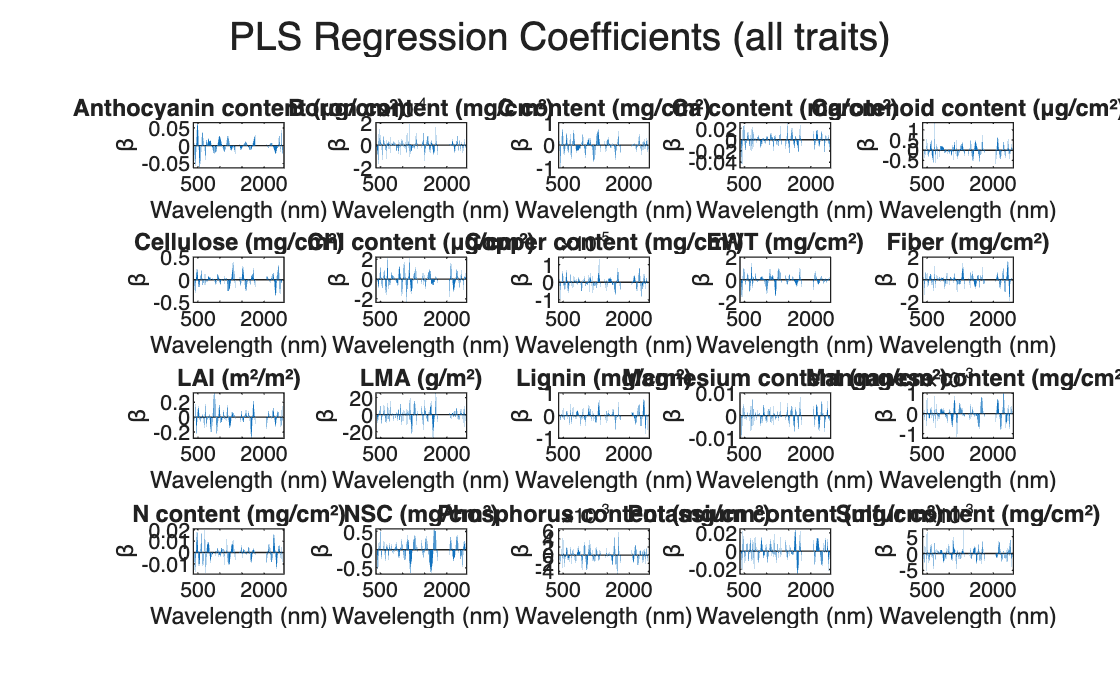

% Define figures for grouped subplots
figure_Betas   = figure('Name','PLS Coefficients');
figure_Scatter = figure('Name','PLS Estimation');
figure_Resid   = figure('Name','PLS Residuals');
figure_SPE     = figure('Name','SPE Control Charts');
figure_T2      = figure('Name','T2 Control Charts');

% Preallocate storage for all traits
Q2_all      = zeros(20, 25);
RMSE_all    = zeros(20, 25);
R2X_all     = zeros(20, 25);
R2Y_all     = zeros(20, 25);
Q2_test_all = zeros(1, 20);
RMSE_test_all = zeros(1, 20);

for traitIdx = 1:20
    %% Trait to predict
    Ytrait = traits_data(:, traitIdx);
    traitMiss = isnan(Ytrait);
    Ytrait = Ytrait(~traitMiss, :);
    Xtrait = spectra_data(~traitMiss, :);

    %% Data division
    model(traitIdx).X0 = Xtrait;
    model(traitIdx).Y0 = Ytrait;
    
    % number of observation
    nobs    = length(model(traitIdx).Y0);
    % cross validation
    part    = cvpartition(nobs, 'HoldOut', 0.3);
    % train/test indices
    idxCal  = training(part);
    idxTest = test(part);
    
    % z-score standardize
    [model(traitIdx).XCal, model(traitIdx).mu, model(traitIdx).sigma] = zscore(model(traitIdx).X0(idxCal, :));
    model(traitIdx).XTest = normalize(model(traitIdx).X0(idxTest,:), 'center', model(traitIdx).mu, 'scale', model(traitIdx).sigma);
    
    % mean centering
    model(traitIdx).YCal = model(traitIdx).Y0(idxCal) - mean(model(traitIdx).Y0(idxCal));
    model(traitIdx).YTest = model(traitIdx).Y0(idxTest) - mean(model(traitIdx).Y0(idxCal));

    %% Cross-validation setup
    X = model(traitIdx).X0(idxCal, :);
    Y = model(traitIdx).Y0(idxCal);
    k = 5;
    cv = cvpartition(size(Y, 1), 'KFold', k);

    PRESSPLS = zeros(k,25);
    Q2PLS    = zeros(k,25);
    RMSEPLS  = zeros(k,25);

    for i = 1:cv.NumTestSets
        % cross validation folds
        trainIdx = training(cv, i);
        testIdx  = test(cv, i);

        X_cal  = X(trainIdx, :);
        Y_cal  = Y(trainIdx, :);
        X_val  = X(testIdx, :);
        Y_val  = Y(testIdx, :);
        
        % z-score
        [XCal, mu, sigma] = zscore(X_cal);
        XVal = normalize(X_val, "center", mu, "scale", sigma);
        
        % mean centering
        YCal = Y_cal - mean(Y_cal);
        YVal = Y_val - mean(Y_cal);
        
        TSS = sum((YVal - mean(YCal)).^2);
        [rows, ~] = size(XVal);

        for j = 1:25
            [~, ~, ~, ~, bPLS] = plsregress(XCal, YCal, j);
            YPredPLS = [ones(rows,1) XVal] * bPLS;
            PRESSPLS(i,j) = sum((YVal - YPredPLS).^2);
            Q2PLS(i,j) = 1 - PRESSPLS(i,j)/TSS;
            RMSEPLS(i,j) = sqrt(mean((YPredPLS - YVal).^2));
        end
    end

    Q2_CV_PLS = mean(Q2PLS);
    RMSE_CV_PLS = mean(RMSEPLS);

    % Store results for combined plots
    Q2_all(traitIdx,:)   = Q2_CV_PLS;
    RMSE_all(traitIdx,:) = RMSE_CV_PLS;

    %% Optimal number of LVs
    threshold = 0.99 * max(Q2_CV_PLS);
    noPCsPLS = find(Q2_CV_PLS >= threshold, 1, 'first');
    if isempty(noPCsPLS)
        noPCsPLS = 3;
    end
    model(traitIdx).nLV = noPCsPLS;   

    %% Final PLS fit
    [P, Q, T, U, bPLS, varPLS, mse, stats] = plsregress(model(traitIdx).XCal, model(traitIdx).YCal, noPCsPLS);

    % Store explained variance
    R2X_all(traitIdx,1:noPCsPLS) = cumsum(varPLS(1,:));
    R2Y_all(traitIdx,1:noPCsPLS) = cumsum(varPLS(2,:));

    %% Predictions
    [row, ~] = size(model(traitIdx).XTest);
    YTestPred = [ones(row, 1) model(traitIdx).XTest] * bPLS;
    resid = abs(model(traitIdx).YTest - YTestPred);

    PRESS_test = sum((YTestPred - model(traitIdx).YTest).^2);
    TSS_test = sum((model(traitIdx).YTest - mean(model(traitIdx).YCal)).^2);
    Q2_test = 1 - PRESS_test / TSS_test;
    RMSE_test = sqrt(mean((model(traitIdx).YTest - YTestPred).^2));

    Q2_test_all(traitIdx) = Q2_test;
    RMSE_test_all(traitIdx) = RMSE_test;

    %% ---- SPE & T² ----
    X_hat = T * P';
    E = model(traitIdx).XCal - X_hat;
    SPE = sum(E.^2, 2);

    covT = cov(T);
    T2 = sum((T / covT) .* T, 2);

    alpha = 0.0027;
    SPE_limit = mean(SPE) + std(SPE)*norminv(1-alpha);
    T2_limit = chi2inv(1-alpha, noPCsPLS);

    %% Plot 3: Coefficients
    figure(figure_Betas);
    subplot(4,5,traitIdx);
    betas = bPLS(2:end);
    bar(wave_lengths, betas);
    title(trait_names(traitIdx));
    xlabel('Wavelength (nm)'); ylabel('β');

    %% Plot 5: Scatter YTest vs YPred
    figure(figure_Scatter);
    subplot(4,5,traitIdx);
    scatter(model(traitIdx).YTest, YTestPred, 'filled');
    xlabel('True'); ylabel('Predicted');
    title(trait_names(traitIdx));
    axis equal;
    text(min(model(traitIdx).YTest), max(YTestPred), sprintf('Q^2=%.2f', Q2_test), 'FontSize',8);

    %% Plot 6: Residuals
    figure(figure_Resid);
    subplot(4,5,traitIdx);
    scatter(model(traitIdx).YTest, resid, 'filled');
    xlabel('True'); ylabel('|Error|');
    title(trait_names(traitIdx));

    %% Plot 7: SPE Control Chart
    figure(figure_SPE);
    subplot(4,5,traitIdx);
    plot(SPE, 'bo-','MarkerSize',3); hold on;
    yline(SPE_limit,'r--','Limit');
    title(trait_names(traitIdx));
    xlabel('Sample'); ylabel('SPE'); hold off;

    %% Plot 8: T² Control Chart
    figure(figure_T2);
    subplot(4,5,traitIdx);
    plot(T2, 'ko-','MarkerSize',3); hold on;
    yline(T2_limit,'r--','Limit');
    title(trait_names(traitIdx));
    xlabel('Sample'); ylabel('T^2'); hold off;
end

% Super titles
sgtitle(figure_Betas, 'PLS Regression Coefficients (all traits)');

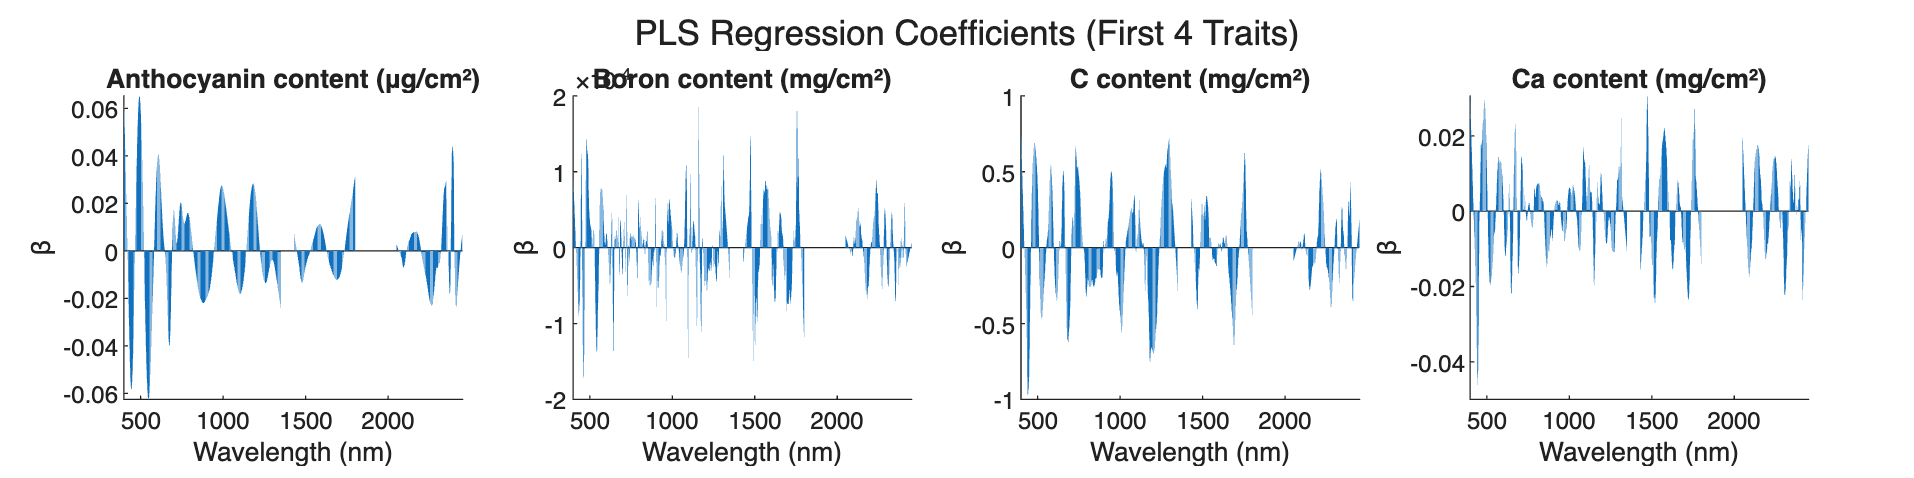

% first 4 shbfigure
origFig = figure_Betas;

axs = flipud(findobj(origFig, 'Type', 'axes')); 
axs = axs(arrayfun(@(a) isempty(get(a,'Tag')) || ~any(strcmp(get(a,'Tag'),{'legend','Colorbar'})), axs));

n = min(4, numel(axs));

newFig = figure('Name','PLS First 4','Color','w');
tl = tiledlayout(newFig, 1, n, 'TileSpacing','compact', 'Padding','compact');

for k = 1:n
    src = axs(k);
    dst = nexttile(tl, k);
    copyobj(allchild(src), dst);
    set(dst, 'XLim', get(src,'XLim'), 'YLim', get(src,'YLim'));
    grid(dst, src.XGrid);
    title(dst, src.Title.String);
    xlabel(dst, src.XLabel.String);
    ylabel(dst, src.YLabel.String);
end

sgtitle(newFig, 'PLS Regression Coefficients (First 4 Traits)');

height = 400; 
width = 4 * height;
set(newFig, 'Position', [100 100 width height]);

exportgraphics(newFig, 'PLS_conf_first4.pdf', 'ContentType', 'vector');

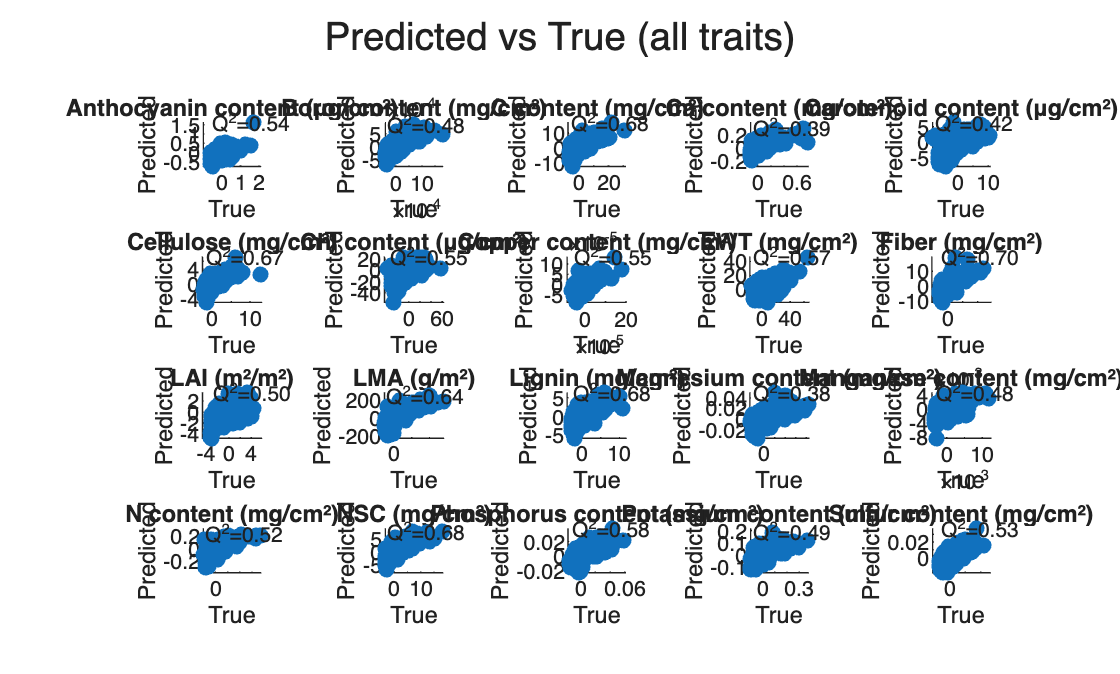

sgtitle(figure_Scatter, 'Predicted vs True (all traits)');

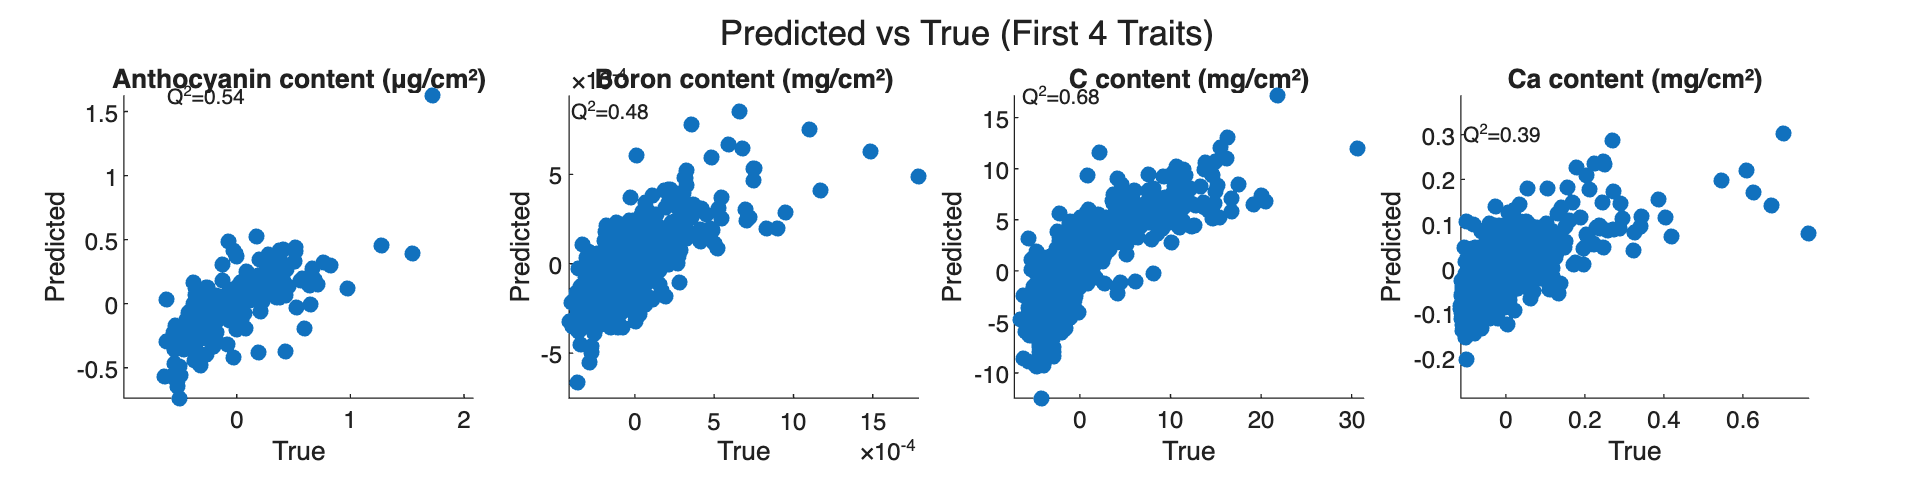

% first 4 shbfigure
origFig = figure_Scatter;

axs = flipud(findobj(origFig, 'Type', 'axes'));
axs = axs(arrayfun(@(a) isempty(get(a,'Tag')) || ~any(strcmp(get(a,'Tag'),{'legend','Colorbar'})), axs));

n = min(4, numel(axs));

newFig = figure('Name','Predicted vs True First 4','Color','w');
tl = tiledlayout(newFig, 1, n, 'TileSpacing','compact', 'Padding','compact');

for k = 1:n
    src = axs(k);
    dst = nexttile(tl, k);
    copyobj(allchild(src), dst);
    set(dst, 'XLim', get(src,'XLim'), 'YLim', get(src,'YLim'));
    grid(dst, src.XGrid);
    title(dst, src.Title.String);
    xlabel(dst, src.XLabel.String);
    ylabel(dst, src.YLabel.String);
end

sgtitle(newFig, 'Predicted vs True (First 4 Traits)');

height = 400;
width = 4 * height;
set(newFig, 'Position', [100 100 width height]);
exportgraphics(newFig, 'predicted_vs_true_first4.pdf', 'ContentType', 'vector');

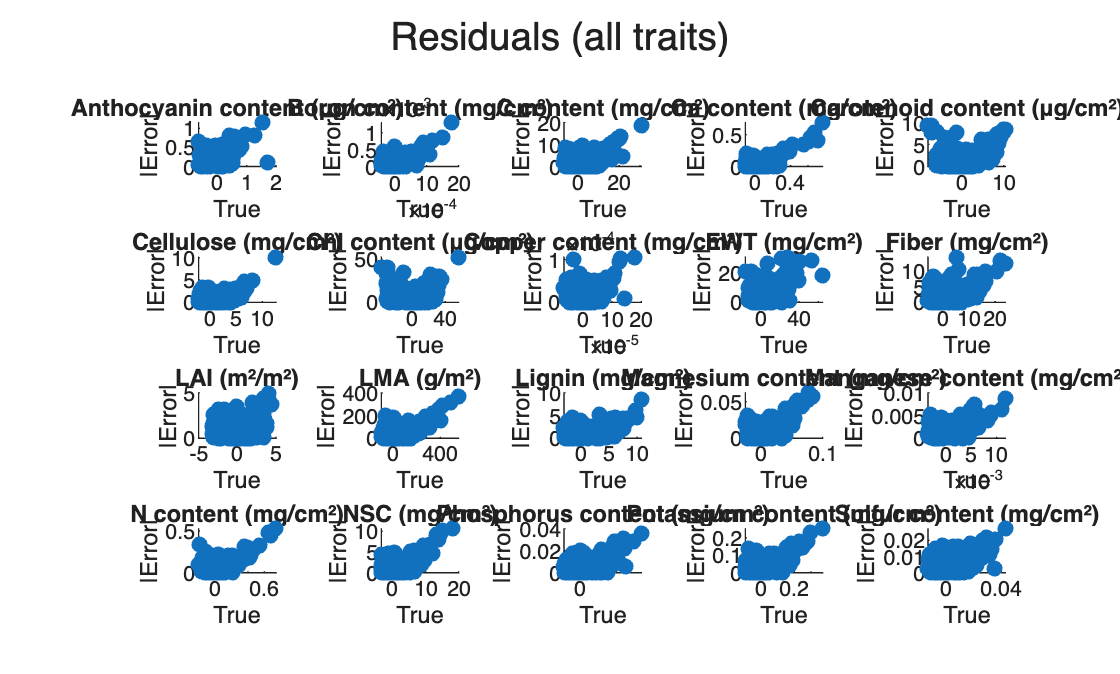

sgtitle(figure_Resid, 'Residuals (all traits)');

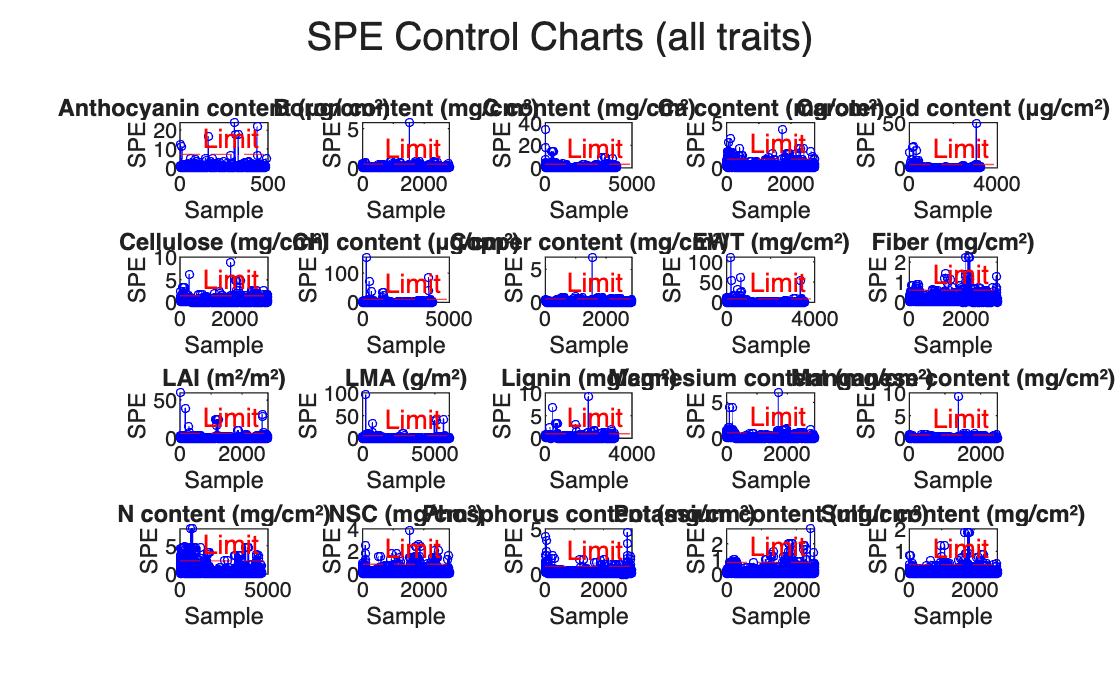

sgtitle(figure_SPE, 'SPE Control Charts (all traits)');

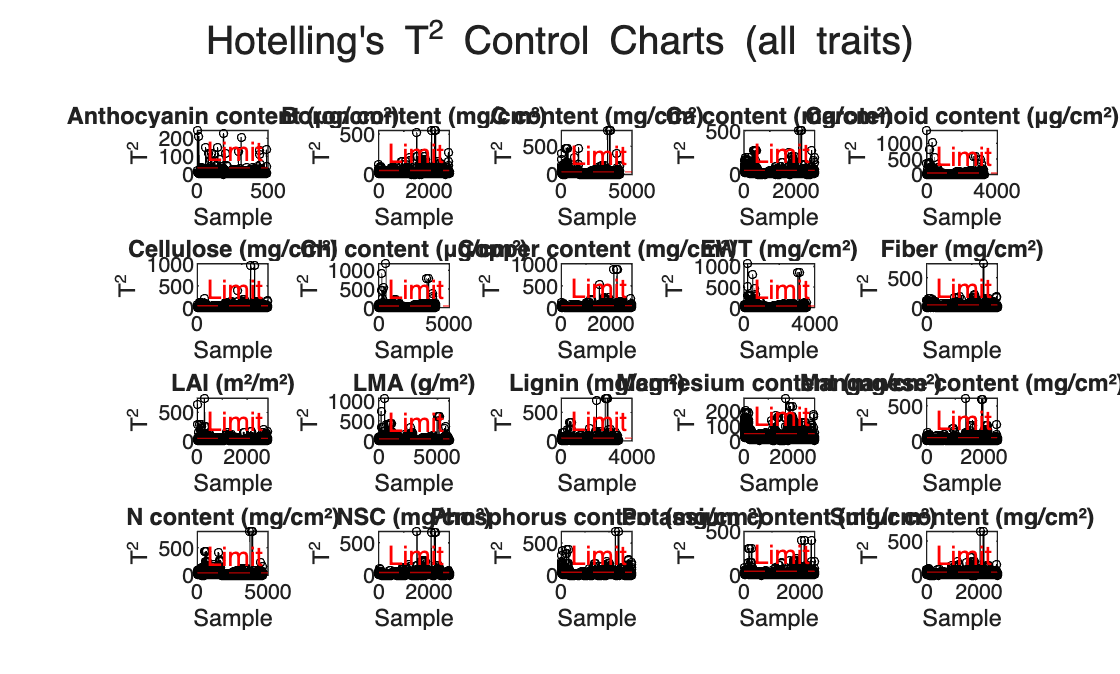

sgtitle(figure_T2, 'Hotelling''s T^2 Control Charts (all traits)');

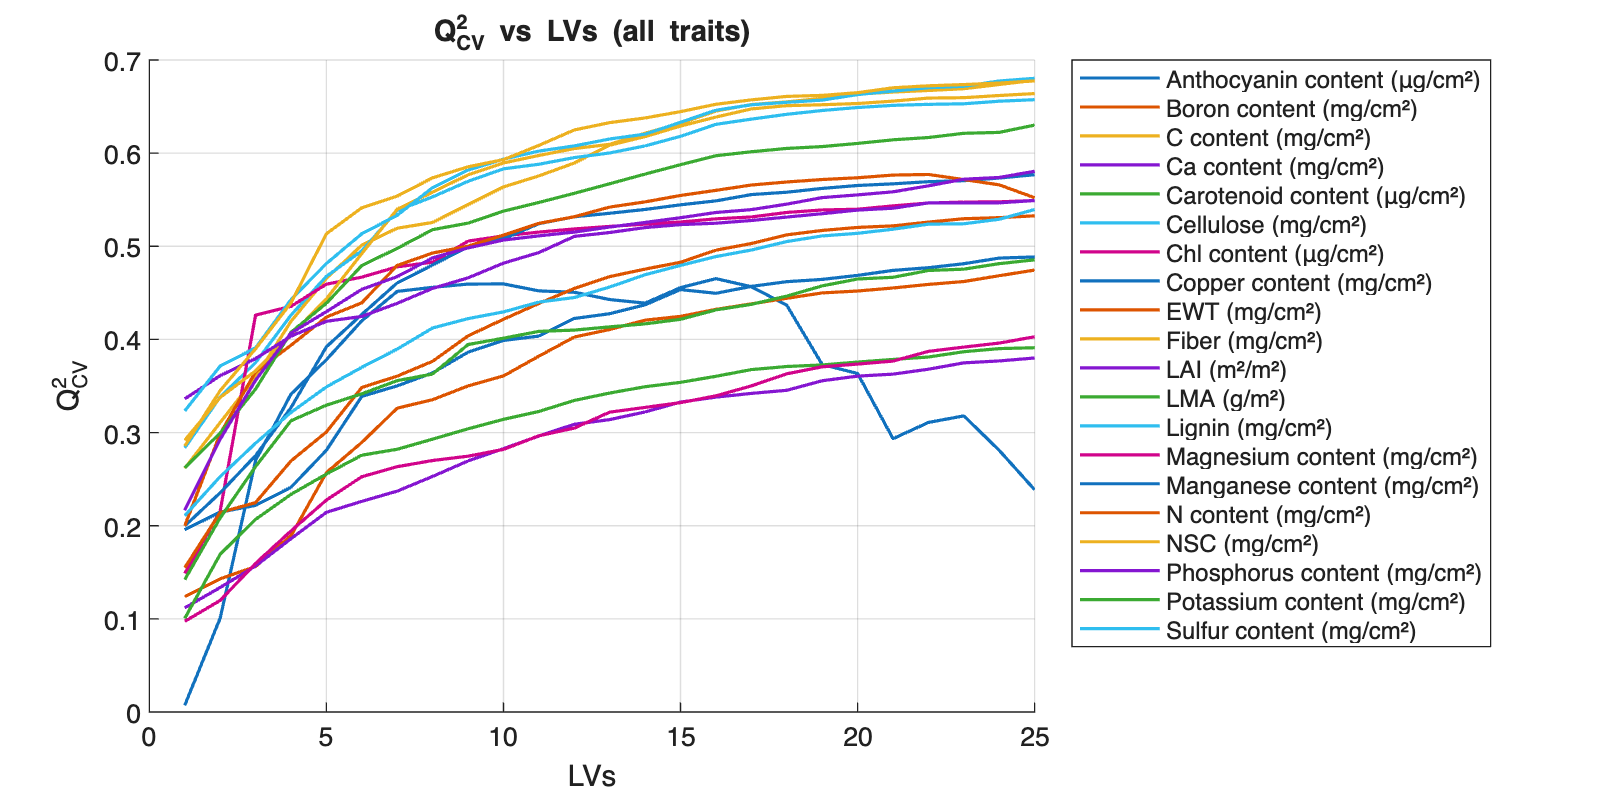

% Q² across traits
figure;
hold on;
plot(1:25, Q2_all', 'LineWidth', 1.2);
xlabel('LVs');
ylabel('Q^2_{CV}');
title('Q^2_{CV} vs LVs (all traits)');
legend(trait_names, 'Location','bestoutside');

height = 400;
width = 2 * height;
set(gcf, 'Position', [100 100 width height]);

exportgraphics(gcf, 'Q2_all.pdf', 'ContentType', 'vector');

grid on;
hold off;

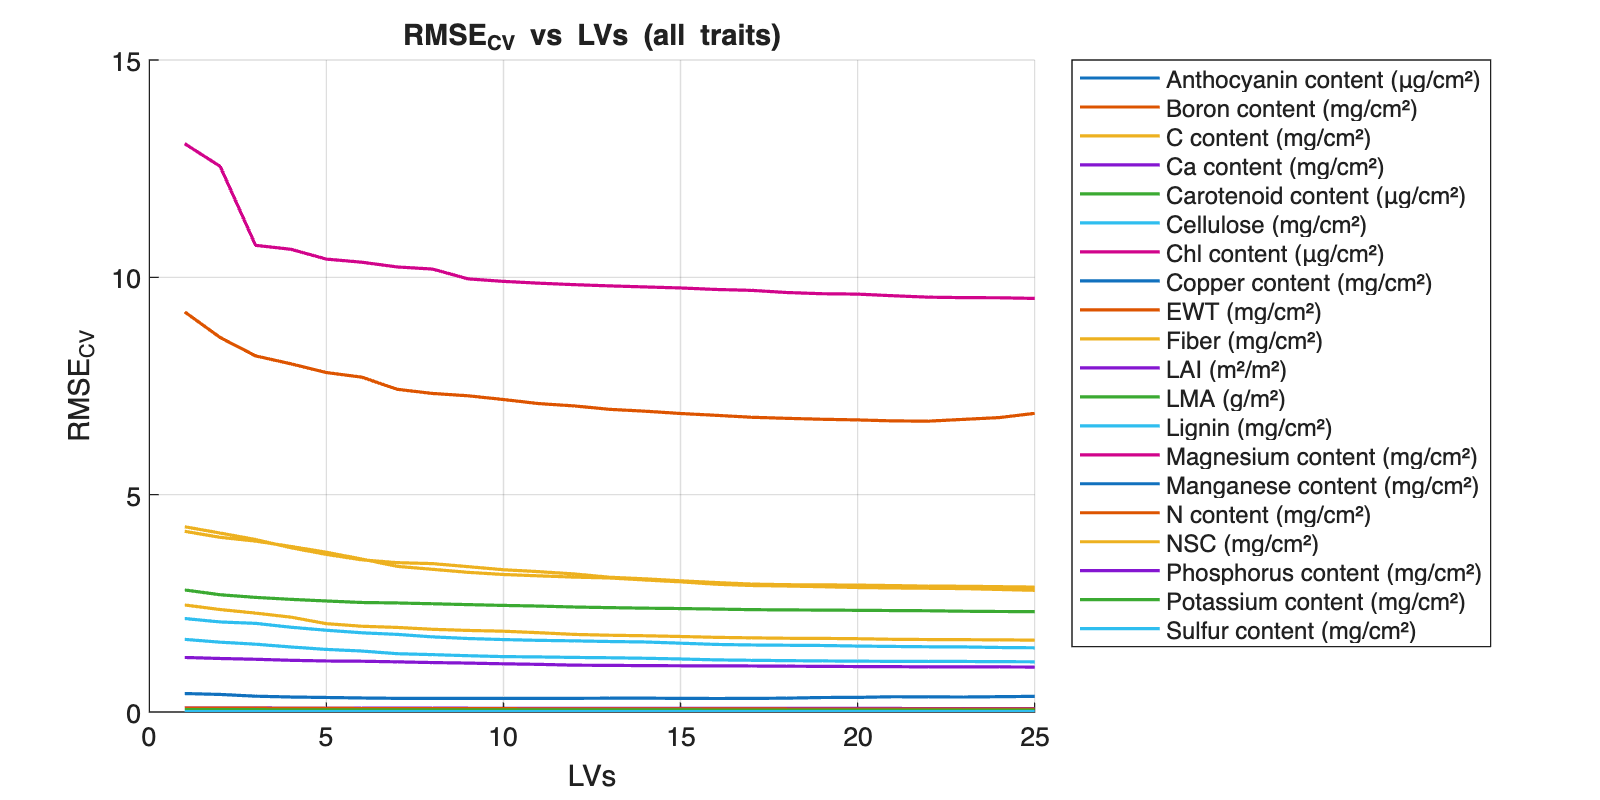

%% Combined Plots Across Traits

% RMSE across traits
figure;
hold on;
plot(1:25, RMSE_all', 'LineWidth', 1.2);
xlabel('LVs');
ylabel('RMSE_{CV}');
title('RMSE_{CV} vs LVs (all traits)');
legend(trait_names, 'Location','bestoutside');
ylim([0 15]);

height = 400;
width = 2 * height;
set(gcf, 'Position', [100 100 width height]);

exportgraphics(gcf, 'RMSE_all.pdf', 'ContentType', 'vector');

grid on;
hold off;

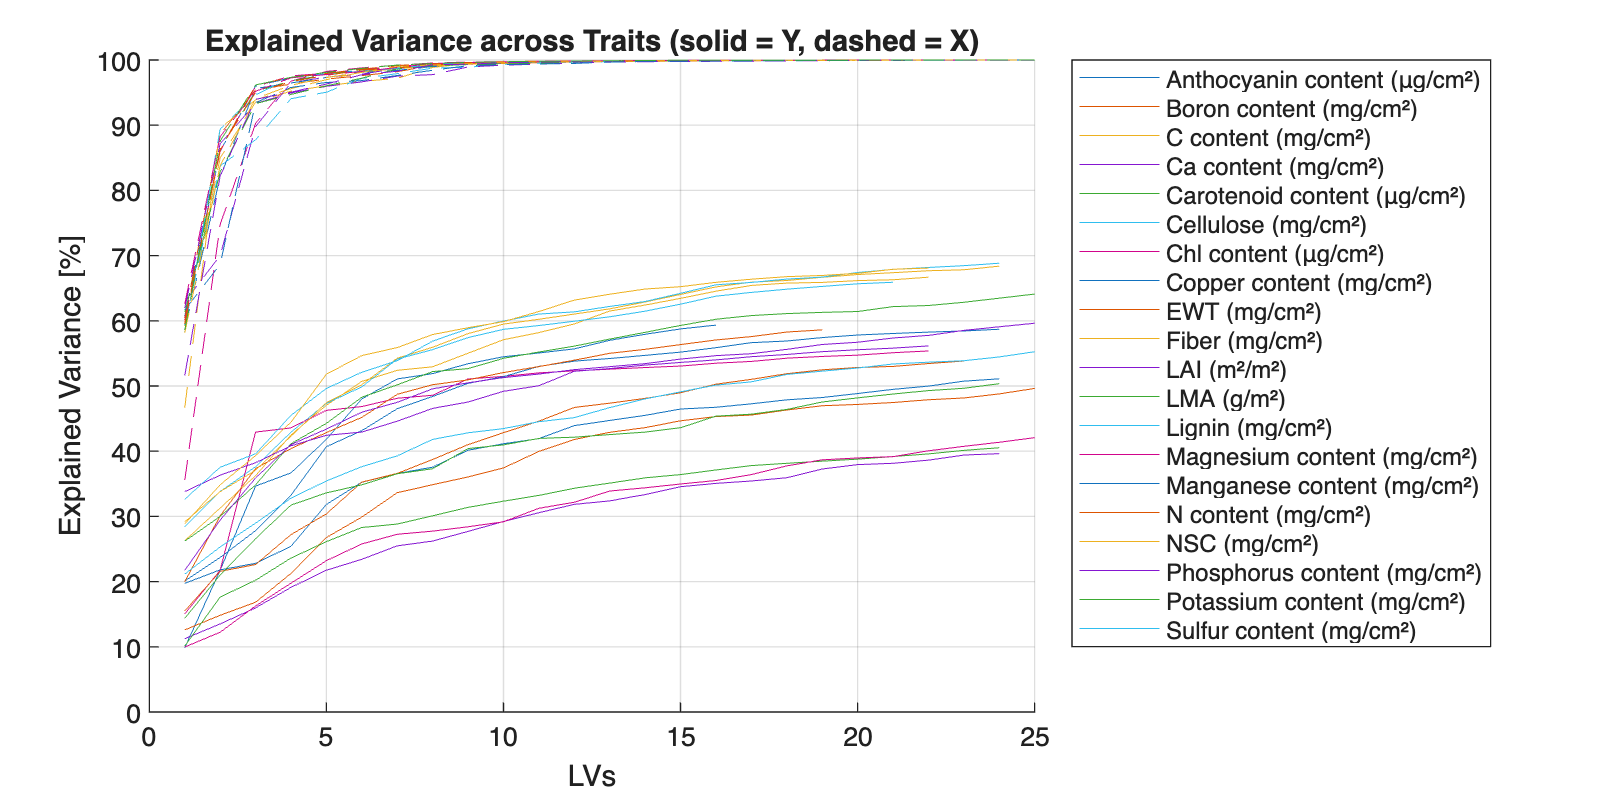

% Explained variance (Y and X) across traits
figure; hold on;
for traitIdx = 1:20
    % Determine valid number of LVs for this trait
    validLVs = model(traitIdx).nLV;
    % Only plot up to validLVs
    plot(1:validLVs, R2Y_all(traitIdx,1:validLVs)*100, '-', 'LineWidth', 0.3);
end
for traitIdx = 1:20
    % Determine valid number of LVs for this trait
    validLVs = model(traitIdx).nLV;
    % Only plot up to validLVs
    plot(1:validLVs, R2X_all(traitIdx,1:validLVs)*100, '--', 'LineWidth', 0.3);
end
xlabel('LVs');
ylabel('Explained Variance [%]');
title('Explained Variance across Traits (solid = Y, dashed = X)');
legend(trait_names, 'Location','bestoutside');

height = 400;
width = 2 * height;
set(gcf, 'Position', [100 100 width height]);
exportgraphics(gcf, 'explained_variance_all.pdf', 'ContentType', 'vector');

grid on; hold off;

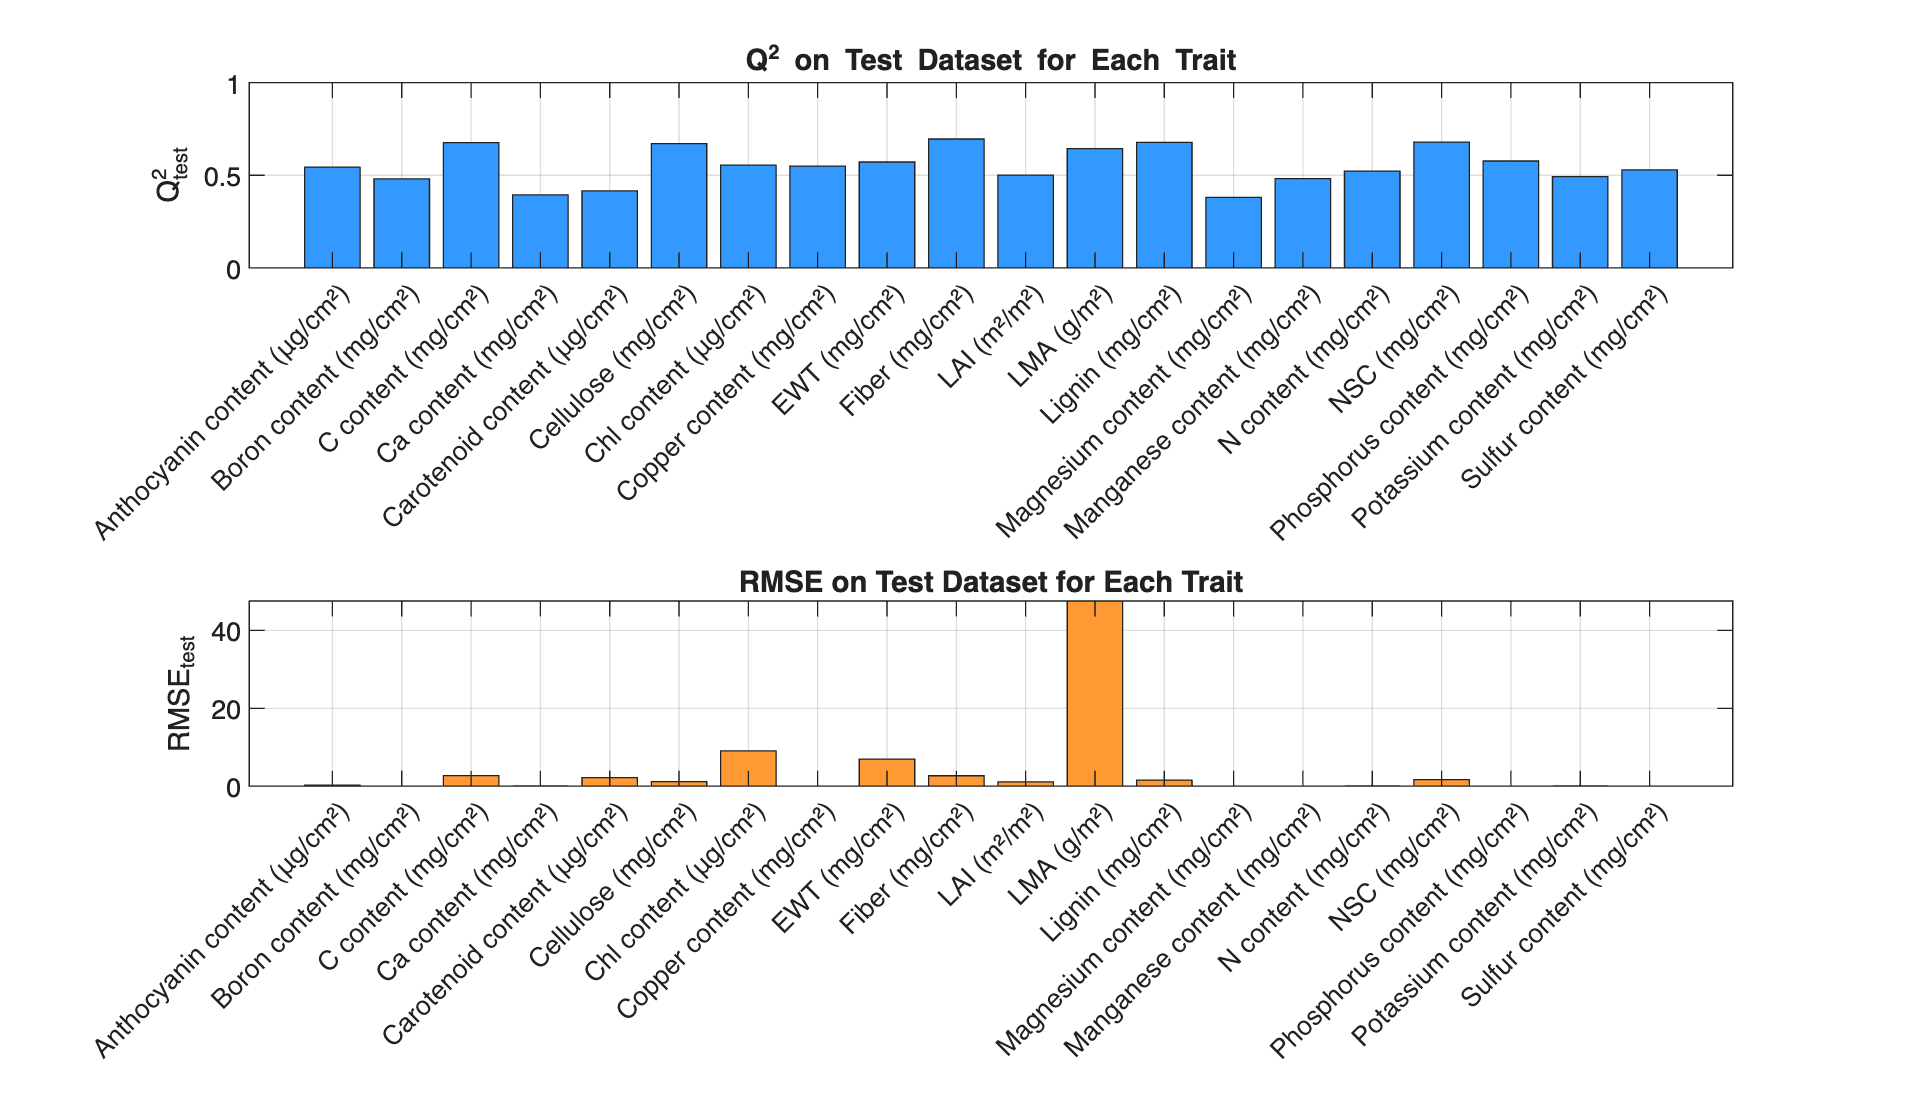

%% Plot overall Q² and RMSE for test sets
figure('Name', 'Test Set Performance');

subplot(2,1,1);
bar(Q2_test_all, 'FaceColor', [0.2 0.6 1]);
ylabel('Q^2_{test}');
title('Q^2 on Test Dataset for Each Trait');
ylim([0 1]);
grid on;

subplot(2,1,2);
bar(RMSE_test_all, 'FaceColor', [1 0.6 0.2]);
ylabel('RMSE_{test}');
title('RMSE on Test Dataset for Each Trait');
grid on;

for i = 1:2
    subplot(2,1,i);
    xticks(1:numel(trait_names));
    xticklabels(trait_names);
    xtickangle(45);
    ax = gca;
    ax.FontSize = 10;
end

height = 800;
width  = 1.75 * height;
set(gcf, 'Position', [100 100 width height]);

exportgraphics(gcf, 'q2_rmse.pdf', 'ContentType', 'vector');

% worst 5
[~, worstIdx] = mink(Q2_test_all, 5);
fprintf('Worst 5 traits by Q^2_{test}: %s\n', mat2str(worstIdx));

Worst 5 traits by Q^2_{test}: [14 4 5 2 15]


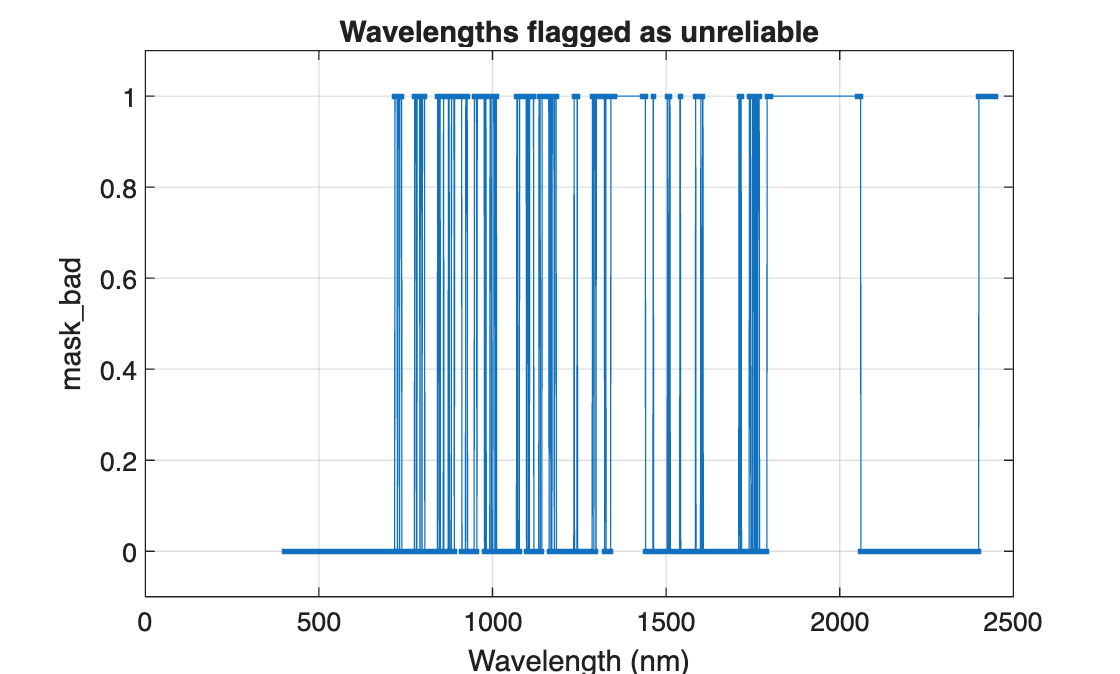


% generate mask_bad
% 1) high
mask_bad = false(size(wave_lengths));
mask_bad = mask_bad | (wave_lengths > 2400);

% 2) SNR and residual filter
use_unsupervised = true;
if use_unsupervised
    nT = numel(worstIdx);
    nW = numel(wave_lengths);
    SNR_all = zeros(nT, nW);
    rmsRes_all = zeros(nT, nW);

    for i = 1:nT
        t = worstIdx(i);
        Xcal_raw = model(t).XCal .* model(t).sigma + model(t).mu;

        % SNR: median / MAD
        medv = median(Xcal_raw, 1);
        madv = mad(Xcal_raw, 1, 1) + eps;
        SNR_all(i,:) = medv ./ madv;

        % residual filter
        sgX  = sgolayfilt(Xcal_raw, 3, 21, [], 2);
        res  = Xcal_raw - sgX;
        rmsRes_all(i,:) = sqrt(mean(res.^2, 1));
    end

    SNR_mean = median(SNR_all, 1);
    rmsRes_mean = median(rmsRes_all, 1);

    bad_snr = SNR_mean < (median(SNR_mean) * 0.5);
    thr_res = median(rmsRes_mean) + 3*mad(rmsRes_mean,1);
    bad_res = rmsRes_mean > thr_res;

    mask_bad = mask_bad | bad_snr | bad_res;
end

% 3) plot
figure('Name','Bad-wavelength mask (1=remove)');
plot(wave_lengths, double(mask_bad), '.-'); ylim([-0.1 1.1]); grid on;
xlabel('Wavelength (nm)'); ylabel('mask\_bad'); title('Wavelengths flagged as unreliable');

Magnesium content (mg/cm²): nCal=2897, SPE=48, T2=296, common=41


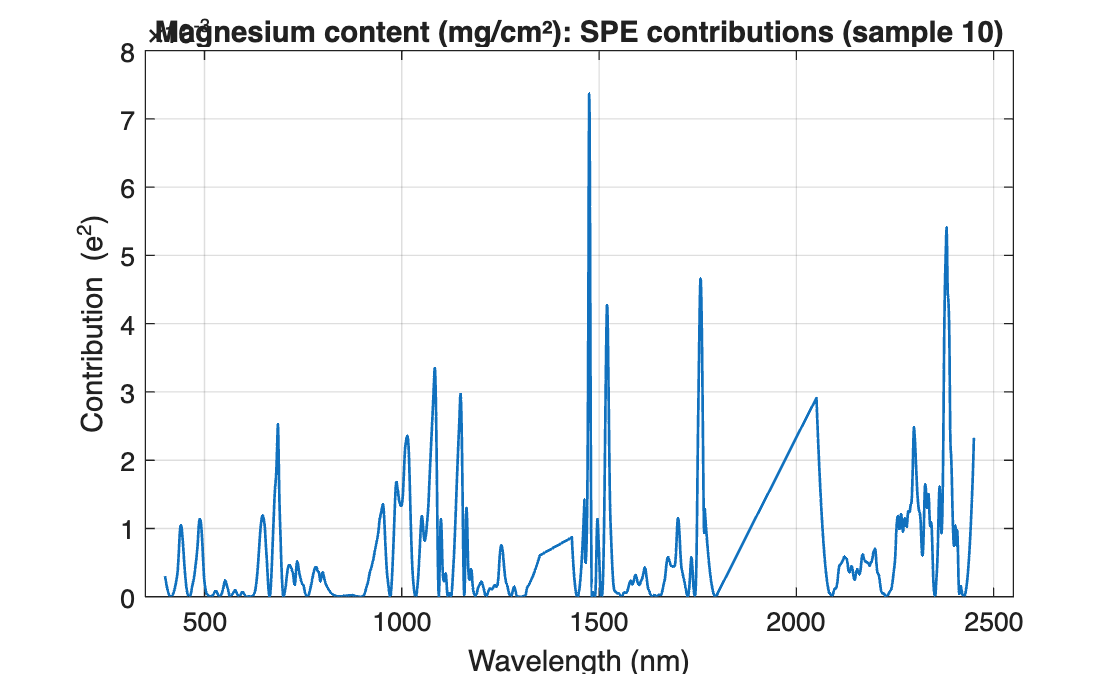

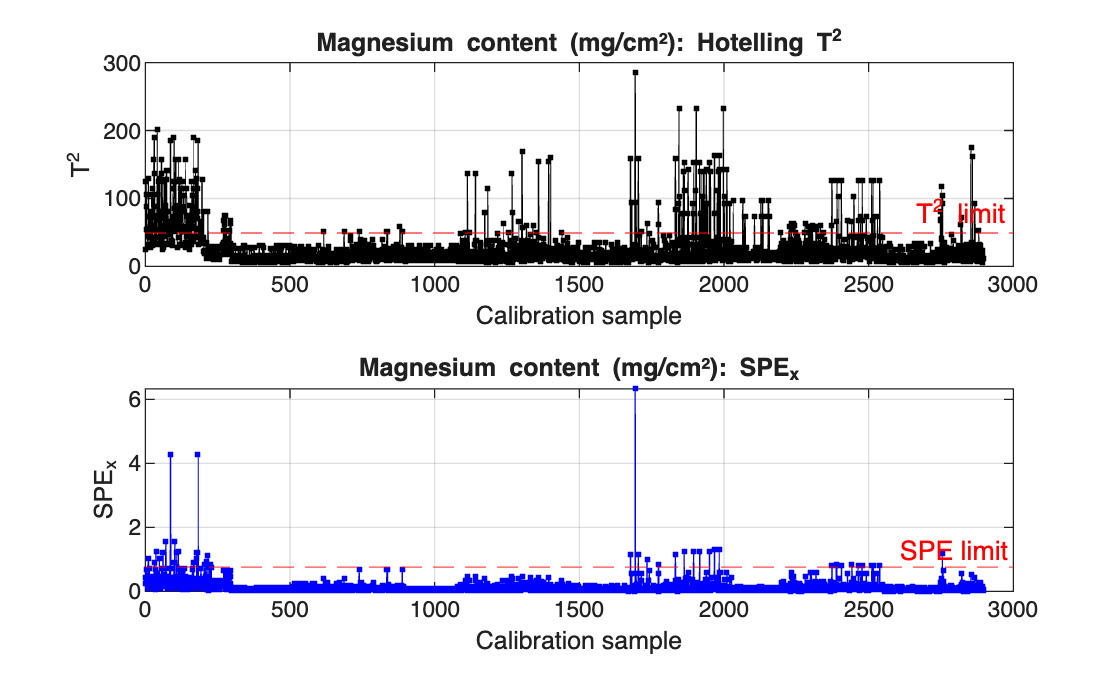

Ca content (mg/cm²): nCal=2744, SPE=65, T2=230, common=49


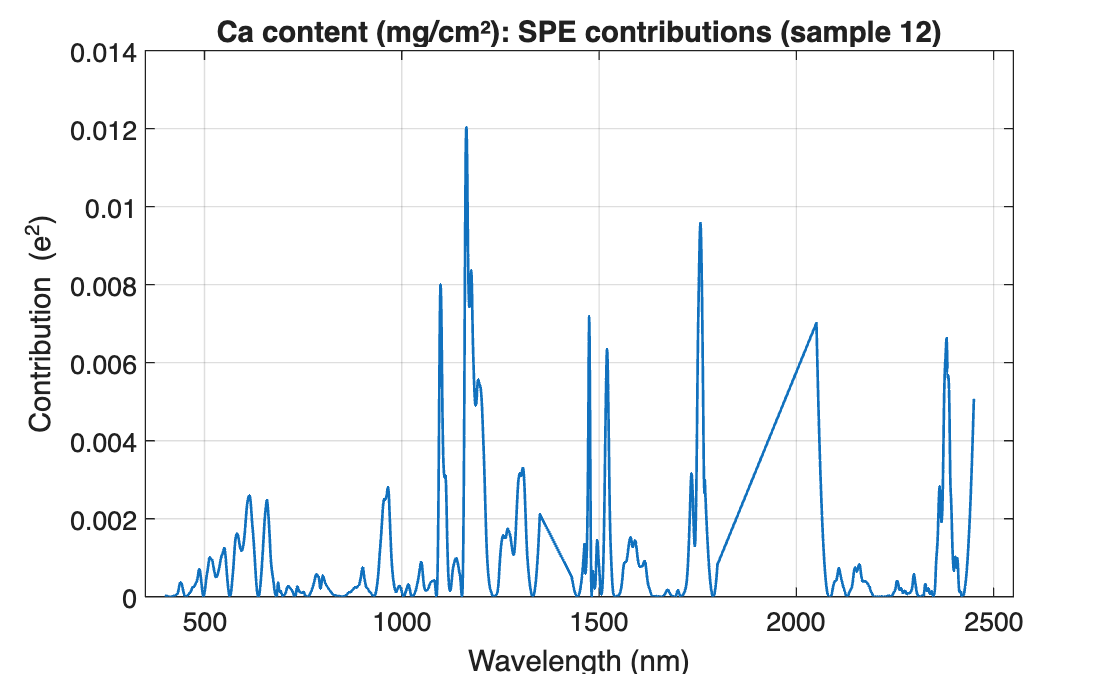

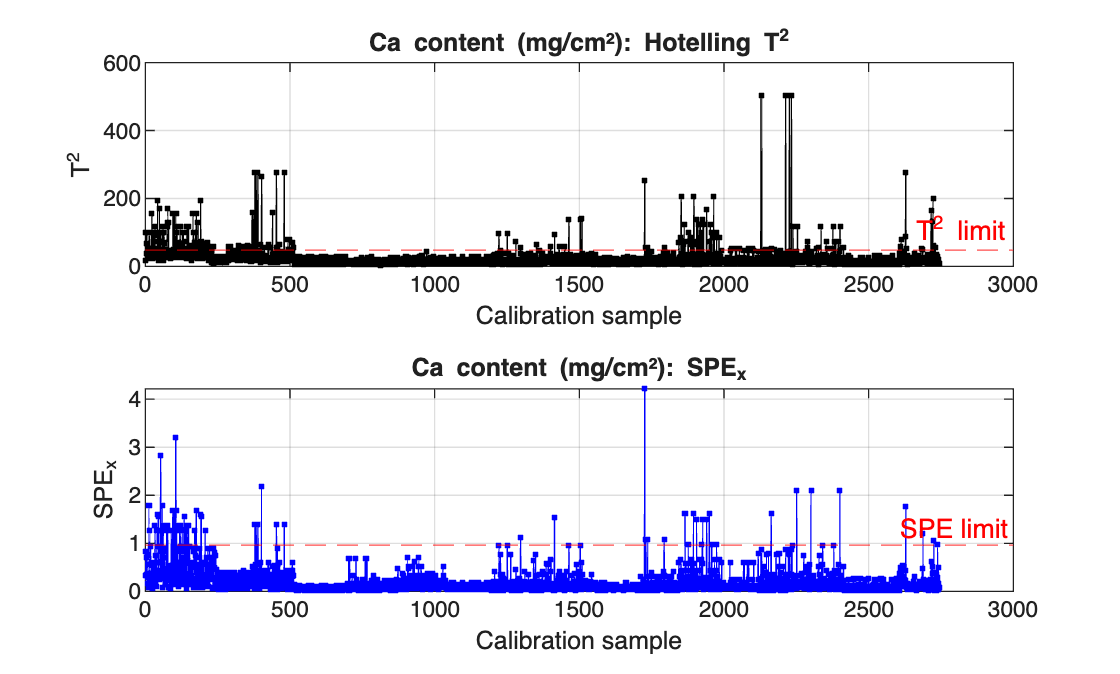

Carotenoid content (μg/cm²): nCal=3250, SPE=15, T2=262, common=15


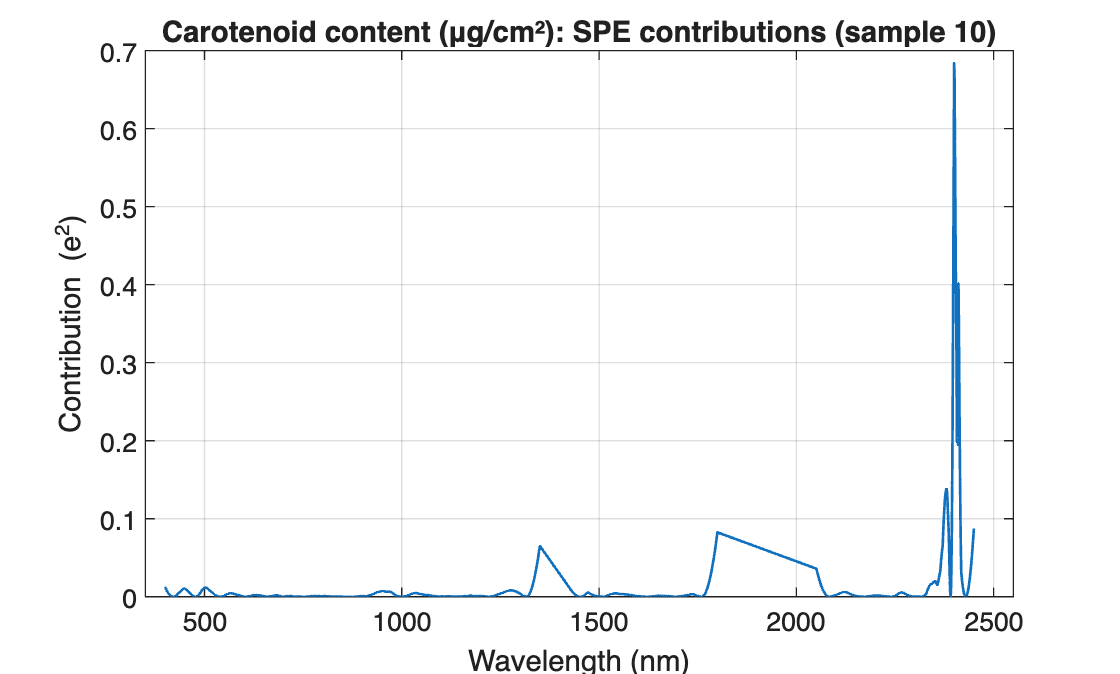

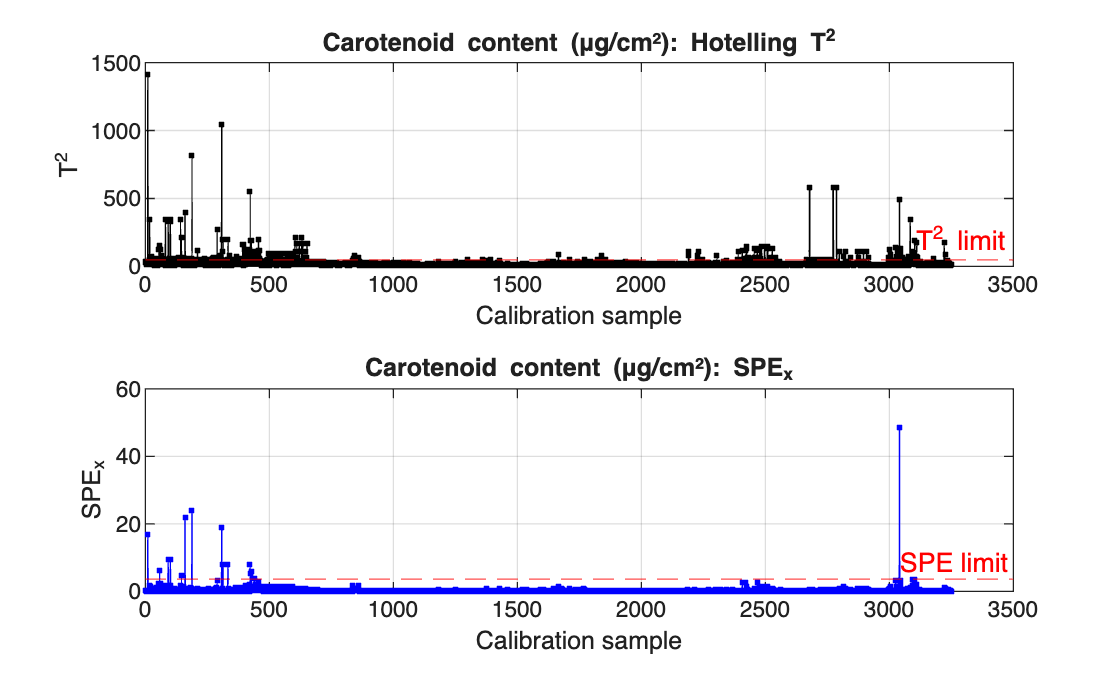

Boron content (mg/cm²): nCal=2821, SPE=35, T2=196, common=30


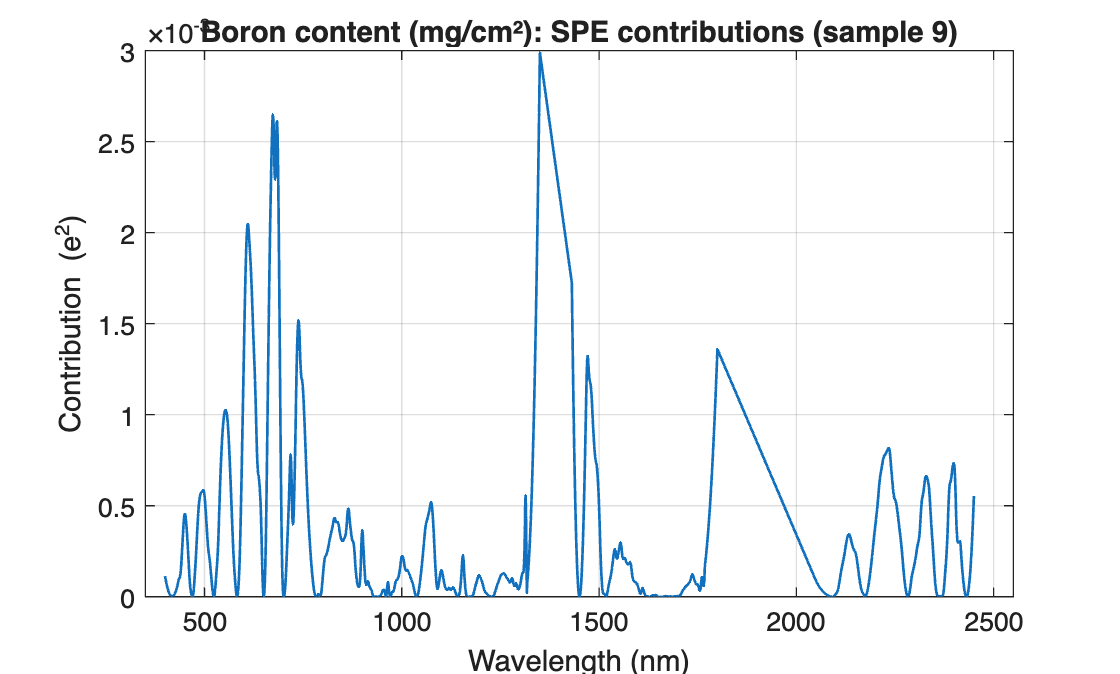

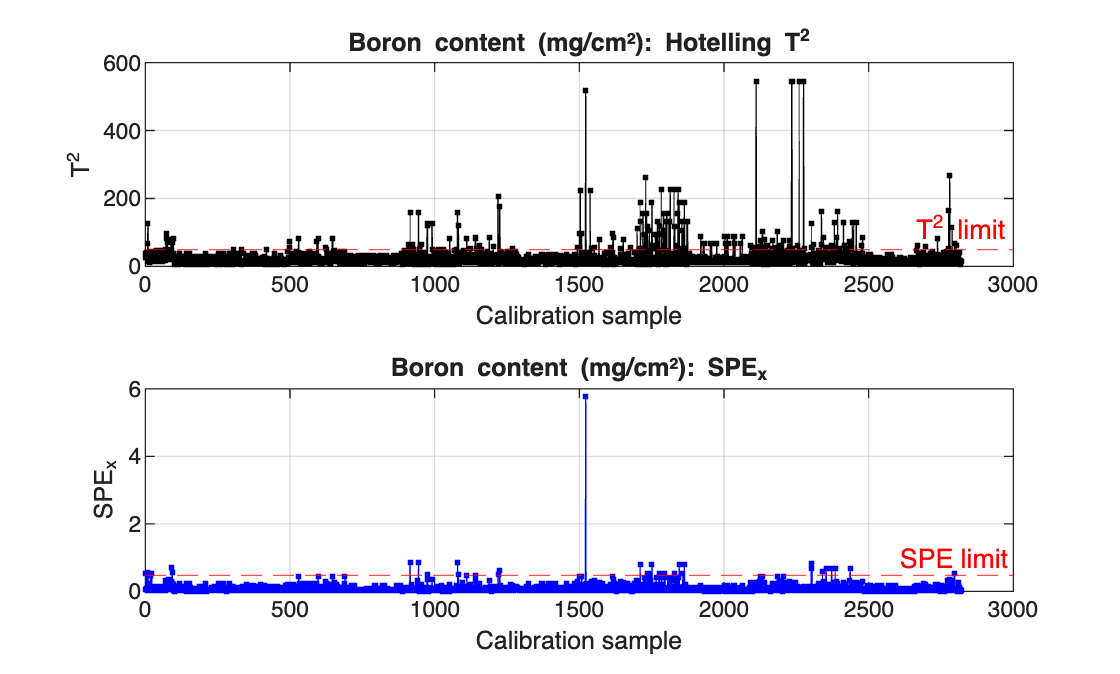

Manganese content (mg/cm²): nCal=2467, SPE=11, T2=147, common=11


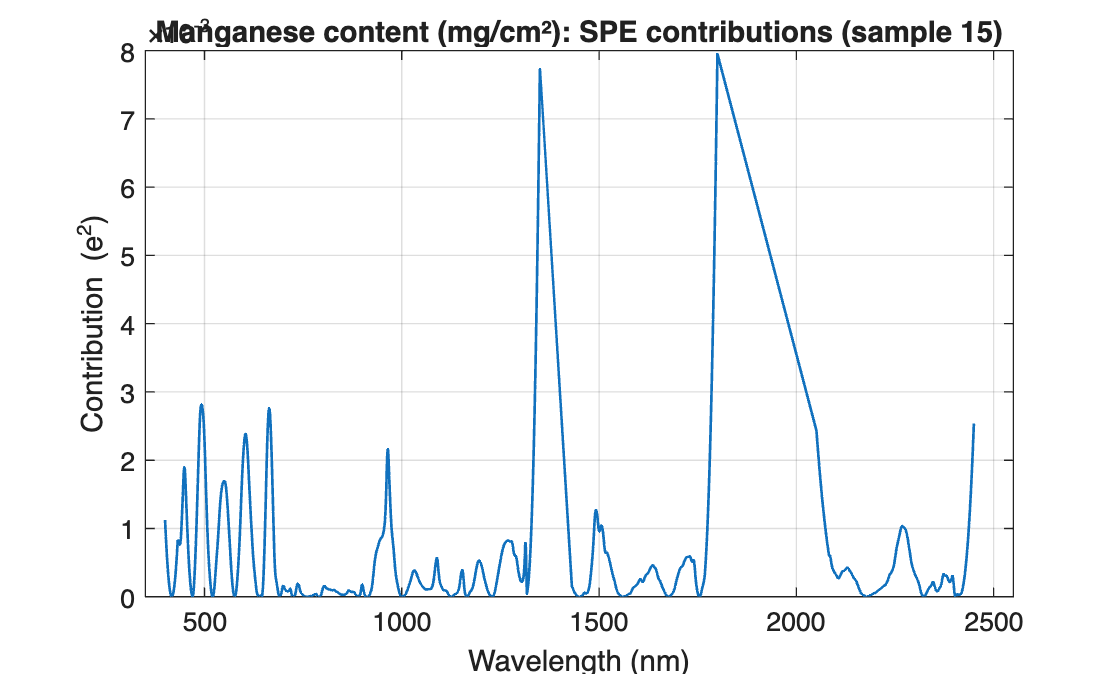

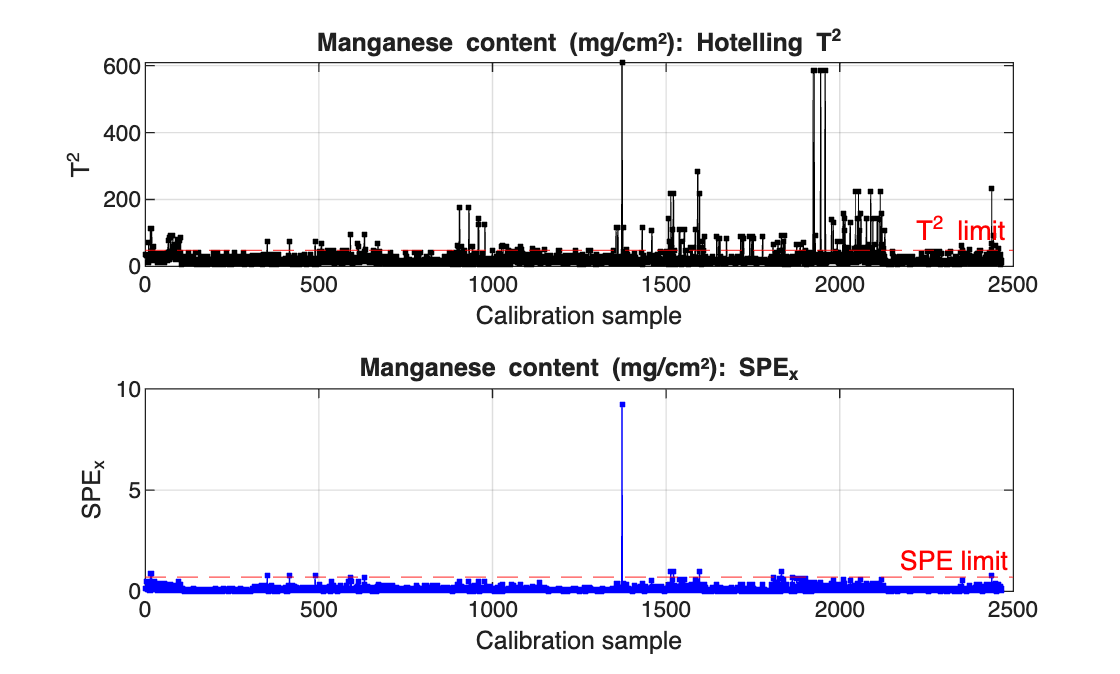

% improvement
Improvement = table('Size',[0 9], ...
    'VariableTypes',{'double','double','double','double','double','double','double','double','double'}, ...
    'VariableNames',{'Trait','nCal','nOutliers','Q2_old','Q2_outlier','RMSE_old','RMSE_outlier','Q2_wcut','RMSE_wcut'});

alpha = 0.0027; % 3σ
show_contrib_plot = true;

% 5 trait
for t = worstIdx(:)'
    % data
    Xcal  = model(t).XCal;
    Ycal  = model(t).YCal;
    Xtest = model(t).XTest;
    Ytest = model(t).YTest;
    A     = model(t).nLV;

    ncal  = size(Xcal,1);

    % baseline
    [P, ~, T, ~, ~] = plsregress(Xcal, Ycal, A);
    Xhat = T * P';
    E    = Xcal - Xhat;

    ST = cov(T); STi = pinv(ST);
    T2 = sum((T * STi) .* T, 2);
    T2_limit = chi2inv(1-alpha, A);

    SPE = sum(E.^2, 2);
    SPE_limit = mean(SPE) + std(SPE) * norminv(1-alpha);

    idx_SPE = find(SPE > SPE_limit);
    idx_T2  = find(T2  > T2_limit);
    exceedIdx = intersect(idx_SPE, idx_T2);
    fprintf('%s: nCal=%d, SPE=%d, T2=%d, common=%d\n', ...
        trait_names{t}, ncal, numel(idx_SPE), numel(idx_T2), numel(exceedIdx));

    % SPE contributions
    if show_contrib_plot
        if ~isempty(exceedIdx), s = exceedIdx(1);
        else, [~, s] = max(SPE); end
        contribSPE = E(s,:).^2;
        figC = figure('Name',sprintf('%s - SPE contributions (sample %d)', trait_names{t}, s));
        plot(wave_lengths, contribSPE, 'LineWidth', 1.0);
        xlabel('Wavelength (nm)'); ylabel('Contribution (e^2)');
        title(sprintf('%s: SPE contributions (sample %d)', trait_names{t}, s));
        grid on; xlim([350 2550]);
        exportgraphics(figC, sprintf('trait_%02d_SPE_contributions.pdf', t), 'ContentType','vector');
    end

    % baseline metrics
    Q2_old   = Q2_test_all(t);
    RMSE_old = RMSE_test_all(t);

    % remove outliers
    keep_rows = true(ncal,1);
    keep_rows(exceedIdx) = false;

    if any(keep_rows) && sum(keep_rows) > A
        [~, ~, ~, ~, bPLS_out] = plsregress(Xcal(keep_rows,:), Ycal(keep_rows), A);
        Ypred_out  = [ones(size(Xtest,1),1) Xtest] * bPLS_out;

        PRESS_out  = sum((Ytest - Ypred_out).^2);
        TSS_out    = sum((Ytest - mean(Ycal)).^2);
        Q2_outlier = 1 - PRESS_out / TSS_out;
        RMSE_outlier = sqrt(mean((Ytest - Ypred_out).^2));
    else
        Q2_outlier = Q2_old;
        RMSE_outlier = RMSE_old;
        warning('%s: insufficient remaining samples for Step-1 refit; keep baseline.', trait_names{t});
    end

    % remove bands
    keep_lam = ~mask_bad;
    Xcal_red  = Xcal(:, keep_lam);
    Xtest_red = Xtest(:, keep_lam);

    A_red = min([A, size(Xcal_red,1)-1, size(Xcal_red,2)]);
    if A_red >= 1
        [~, ~, ~, ~, bPLS_wmask] = plsregress(Xcal_red, Ycal, A_red);
        Ypred_wmask = [ones(size(Xtest_red,1),1) Xtest_red] * bPLS_wmask;

        PRESS_wcut = sum((Ytest - Ypred_wmask).^2);
        TSS_wcut   = sum((Ytest - mean(Ycal)).^2);
        Q2_wcut    = 1 - PRESS_wcut / TSS_wcut;
        RMSE_wcut  = sqrt(mean((Ytest - Ypred_wmask).^2));
    else
        Q2_wcut   = Q2_old;
        RMSE_wcut = RMSE_old;
        warning('%s: insufficient dimension for Step-2 refit; reuse baseline metrics.', trait_names{t});
    end

    % log
    Improvement = [Improvement; {t, ncal, numel(exceedIdx), ...
        Q2_old, Q2_outlier, RMSE_old, RMSE_outlier, Q2_wcut, RMSE_wcut}]; %#ok<AGROW>

    % plot
    figCtrl = figure('Name',sprintf('Trait %d - Control Charts', t));
    tiledlayout(2,1);
    nexttile; plot(T2,'k.-'); hold on; yline(T2_limit,'r--','T^2 limit'); hold off;
    xlabel('Calibration sample'); ylabel('T^2');
    title(sprintf('%s: Hotelling T^2', trait_names{t})); grid on;
    nexttile; plot(SPE,'b.-'); hold on; yline(SPE_limit,'r--','SPE limit'); hold off;
    xlabel('Calibration sample'); ylabel('SPE_x');
    title(sprintf('%s: SPE_x', trait_names{t})); grid on;
    exportgraphics(figCtrl, sprintf('trait_%02d_control_charts.pdf', t), 'ContentType','vector');
end

disp('=== A2: Baseline vs Remove-outliers vs Remove-bad-wavelengths ===');

=== A2: Baseline vs Remove-outliers vs Remove-bad-wavelengths ===


Improvement

Improvement = 5×9 table
    Trait    nCal    nOutliers    Q2_old     Q2_outlier     RMSE_old     RMSE_outlier    Q2_wcut    RMSE_wcut 
    _____    ____    _________    _______    __________    __________    ____________    _______    __________

     14      2897       41        0.38016     0.36552        0.012071       0.012212     0.38775      0.011997
      4      2744       49        0.39406     0.38857        0.081348       0.081716     0.39635      0.081195
      5      3250       15        0.41556     0.38766          2.1915         2.2432     0.41684        2.1891
      2      2821       30        0.47994     0.48271      0.00016903     0.00016857     0.47731    0.00016945
   

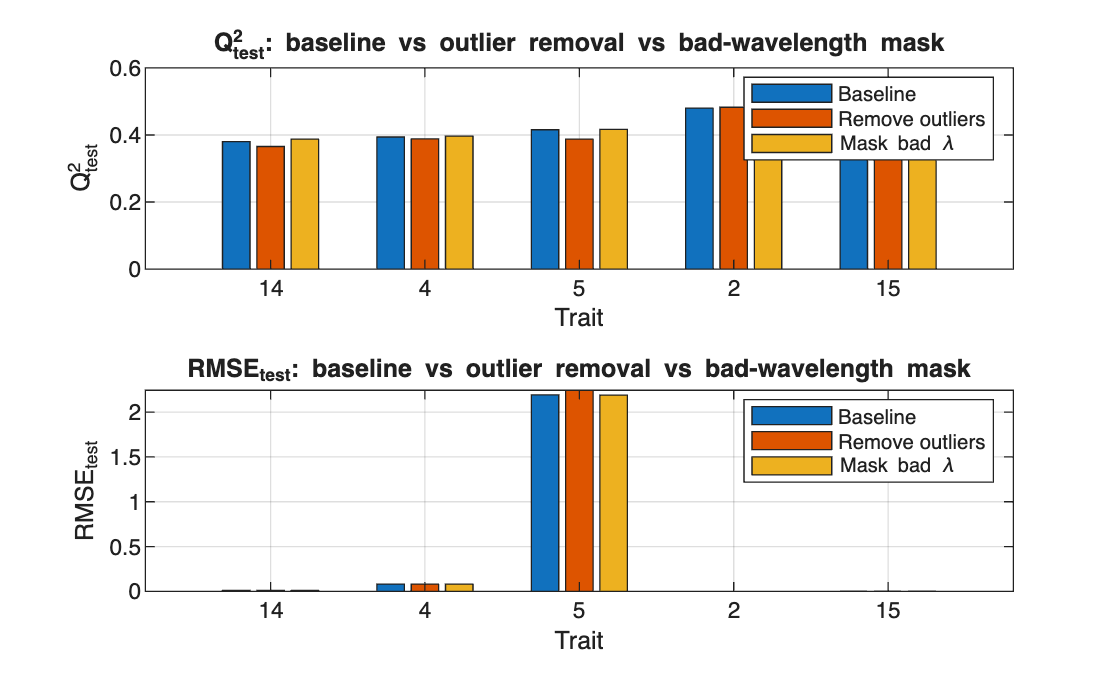


figure('Name','Impact of outlier removal & bad-wavelength masking'); 
tiledlayout(2,1);

nexttile;
x = categorical(string(Improvement.Trait));
x = reordercats(x, string(Improvement.Trait));
bar(x, [Improvement.Q2_old, Improvement.Q2_outlier, Improvement.Q2_wcut], 'grouped');
xlabel('Trait'); ylabel('Q^2_{test}');
title('Q^2_{test}: baseline vs outlier removal vs bad-wavelength mask');
legend({'Baseline','Remove outliers','Mask bad \lambda'},'Location','best'); grid on;

nexttile;
bar(x, [Improvement.RMSE_old, Improvement.RMSE_outlier, Improvement.RMSE_wcut], 'grouped');
xlabel('Trait'); ylabel('RMSE_{test}');
title('RMSE_{test}: baseline vs outlier removal vs bad-wavelength mask');
legend({'Baseline','Remove outliers','Mask bad \lambda'},'Location','best'); grid on;